**Tarea 1:**

%load('Tarea3.mat')
addpath('./datos')
addpath('./funciones')

Con los datos en traindata.mat: Diseñar un VQ de 6 bits, utilizando un umbral de parada de 0,001 y ϵ = 0,025. display=1 para representar los datos de partida y los centroides resultantes. Representa cómo varía la distorsión obtenida, vDist, en función de la iteración. 

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


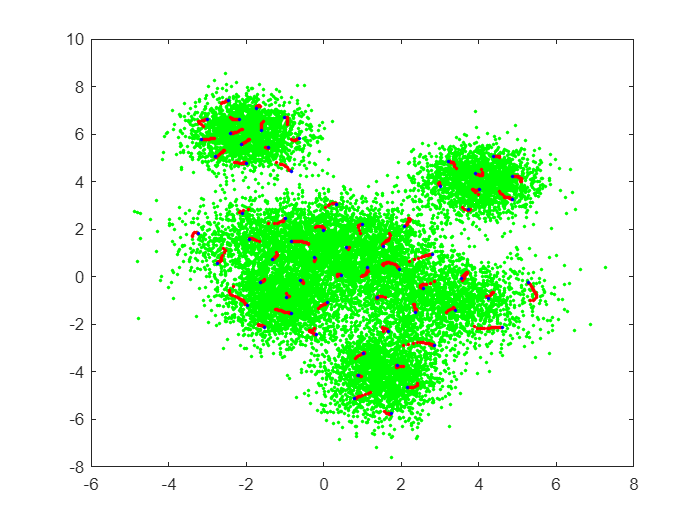


%bsVQ(data, nbits, epsilon, threshold, display)
data = traindata;
nbits = 6;
threshold = 0.001;
epsilon = 0.025;
display = 1;

[VQ vDist] = bsVQ(data, nbits, epsilon, threshold, display);

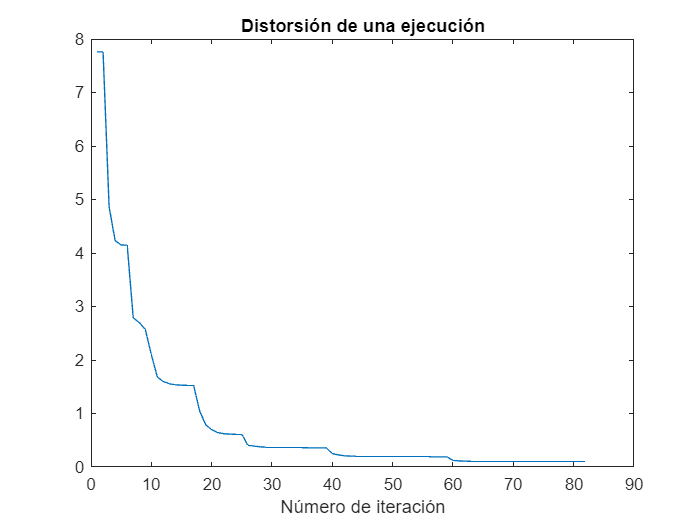

plot(vDist)
title('Distorsión de una ejecución')
xlabel('Número de iteración')
ylabel(' ')

Ejecuta el algoritmo bsVQ 20 veces. Guarda el tiempo de ejecución y la distorsión de la última iteración de cada ejecución. Represéntalos gráficamente. (Ayuda: funciones Matlab clock y etime)

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

for i = 1:20
  horaInicial = clock;
  [VQ vDist] = bsVQ(data, nbits, epsilon, threshold, display);
  horaFinal = clock;
  vectorDistorsion(i,:) = vDist(length(vDist));
  vectorHoras(i,:) = etime(horaFinal, horaInicial);
end

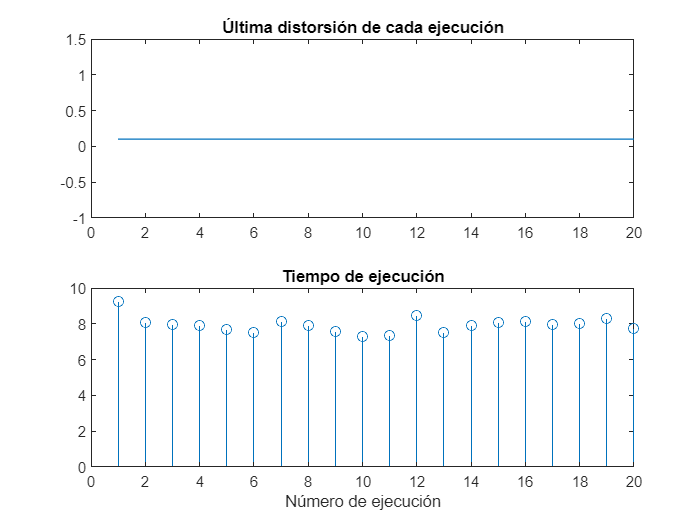


subplot(2,1,1);
  plot(vectorDistorsion)
  title('Última distorsión de cada ejecución')
  %xlabel('Número de ejecución')
subplot(2,1,2); 
  stem(vectorHoras)
  title('Tiempo de ejecución')
  xlabel('Número de ejecución')